# Plotting cages

This guide explains how to create a plot of a particular cage layout

## Initialise cages associated with a model run

Plotting cages is only possible when the cages can be associated with a particular model run and project (rather than the cage file in isolation). This is because the code can discover the project-level model domain and bathymetry information which provides the context for plotting.

So first we have to initialise a particular run.

run = project.solidsRuns.first;

site = run.cages

site =   2 Site array with properties:

    cageGroups: {[4 Depomod.Layout.Cage.Group]  [4 Depomod.Layout.Cage.Group]}
          path: 'C:\newdepomod_projects\bay_of_fish\depomod\cages\bay_of_fish-1.depomodcagesxml'

This returns a `Depomod.Layout.Site` object.

## Plotting cages

Next, we can simply make a plot.

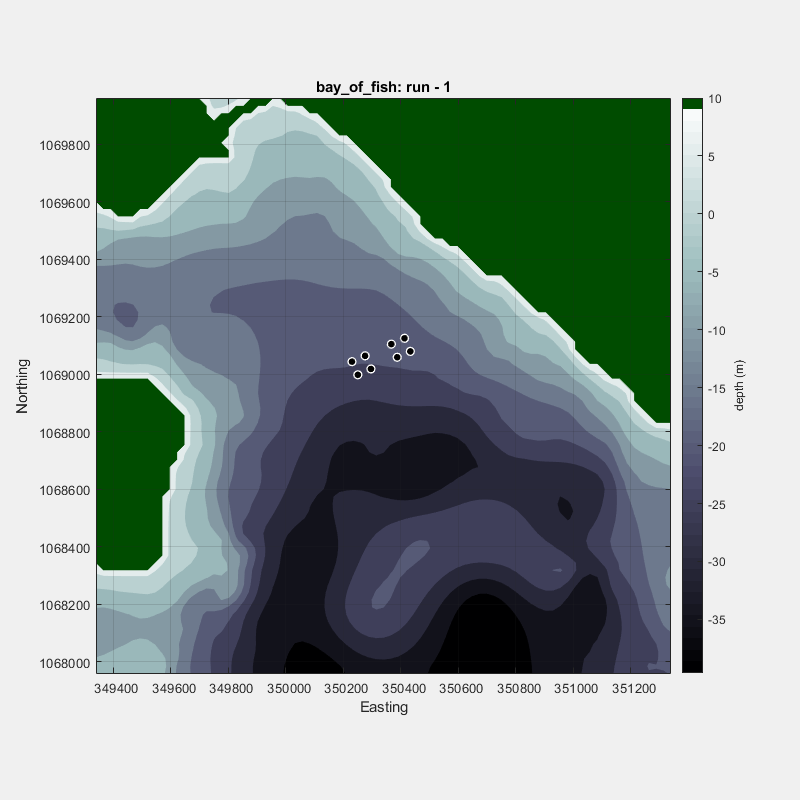

ans =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 0 600 600]
       Units: 'points'

  Show all properties

run.plot('impact', 0)

Notice the impact argument passed in. This is to instruct Matlab not to plot any seabed impacts associated with any model run results files (since we're only interested in the cages here).